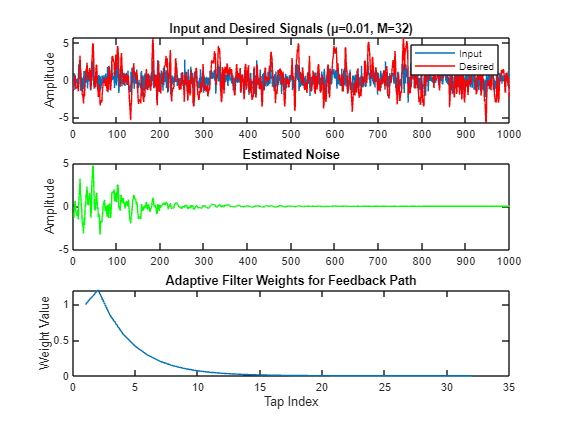

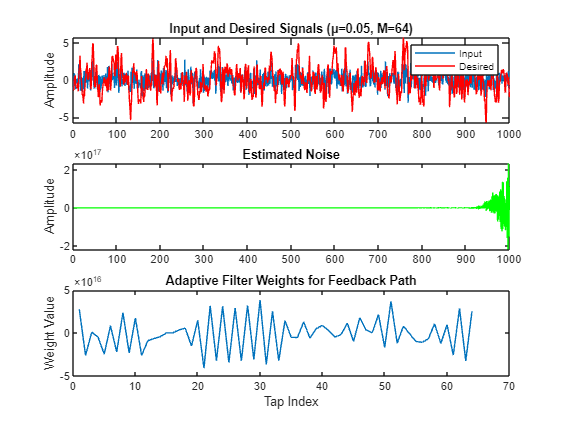

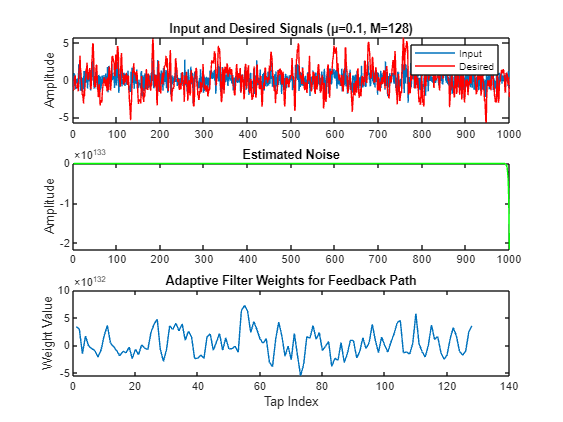

clear all; 
close all; 
clc;

% Parameters for the significant points
significant_points = [
    struct('mu', 0.01, 'M', 32),  % Low μ, Low M
    struct('mu', 0.05, 'M', 64),  % Medium μ, Medium M
    struct('mu', 0.1, 'M', 128)   % High μ, High M
];

% Initialize variables to store results
results = cell(size(significant_points));

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Initialize variables to store SNR improvements
SNR_improvements = zeros(numel(significant_points), 1);

% Loop over the significant points
for k = 1:numel(significant_points)
    mu = significant_points(k).mu;
    M = significant_points(k).M;
    
    % Initialize weight vectors
    w = zeros(M,1);  % Filter weights for feedback path

    % Buffers
    x_buf = zeros(M,1);
    y_buf = zeros(length(d),1);

    % Main loop
    for n = (M+1):length(x)

        % Shift input buffer
        x_buf = x(n:-1:n-M+1); % Fixed indexing

        % FIR filter output for feedback path
        y = w'*x_buf;
        y_buf(n) = y;

        % Error signal (estimated noise)
        e = d(n) - y;

        % Update weight vectors
        w = w + mu * e * x_buf;

    end

    % Calculate Signal-to-Noise Ratio (SNR)
    SNR_input = snr(d, d - x); % SNR of input signal
    SNR_output = snr(d, d - (d - y_buf)); % SNR of output signal (noise-cancelled signal)

    % Store SNR improvement
    SNR_improvement = SNR_output - SNR_input;
    SNR_improvements(k) = SNR_improvement;

    % Store results
    results{k} = struct(...
        'mu', mu, ...
        'M', M, ...
        'SNR_improvement', SNR_improvement, ...
        'w', w, ...
        'y_buf', y_buf ...
    );

    % Plot signals and weights for each significant point
    figure;
    subplot(3,1,1);
    plot(x); hold on; plot(d,'r'); legend('Input','Desired');
    ylabel('Amplitude');
    title(['Input and Desired Signals (μ=' num2str(mu) ', M=' num2str(M) ')']);

    subplot(3,1,2);
    plot(d-results{k}.y_buf,'g'); 
    ylabel('Amplitude');
    title('Estimated Noise');

    subplot(3,1,3);
    plot(w);
    ylabel('Weight Value');
    xlabel('Tap Index');
    title('Adaptive Filter Weights for Feedback Path');
end

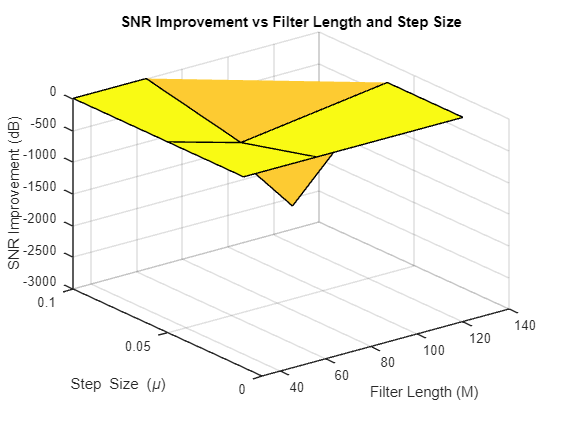


% Create 3D SNR plot
significant_M_values = [32, 64, 128];  % Filter length (M)
significant_mu_values = [0.01, 0.05, 0.1];  % Step size (μ)

% Extract data for 3D plot
SNR_improvements_3d = zeros(numel(significant_M_values), numel(significant_mu_values));

for i = 1:numel(significant_points)
    mu_index = find(significant_mu_values == results{i}.mu);
    M_index = find(significant_M_values == results{i}.M);
    SNR_improvements_3d(M_index, mu_index) = results{i}.SNR_improvement;
end

% Create 3D SNR plot
figure;
surf(significant_M_values, significant_mu_values, SNR_improvements_3d);
xlabel('Filter Length (M)');
ylabel('Step Size (\mu)');
zlabel('SNR Improvement (dB)');
title('SNR Improvement vs Filter Length and Step Size');


% Find the best combination
[max_SNR, idx] = max(SNR_improvements);
best_combination = significant_points(idx);
fprintf('Best combination - Step size (μ): %.2f, Filter length (M): %d\n', best_combination.mu, best_combination.M);

Best combination - Step size (μ): 0.01, Filter length (M): 32
